# Tutorial: OrthoSphere Rendering with Reflectance Models

This software is made available under the MIT license. See SONIC/LICENSE for details.

This live script will demonstrate how to render orthographic projections of spheres with homogenous surfaces using reflectance models provided in `SONIC`. These projections can be used to render images of celestial bodies for applications such as template-matching in horizon-based OPNAV. 

We will utilize `sonic.OrthoSphere` to generate the sphere and corresponding properties such as normal, incidence and emission unit vectors for all points on the sphere. This class assumes that the observer is nadir-viewing and the light source is fixed to the horizontal plane. As such, the sphere can be rendered using just a radius of the sphere in pixels and a phase angle that describes the angle between the observer and incidence vector.

This tutorial is split into three objectives: 

- Generate OrthoSphere Object 

- Generate Reflectance Model Object

- Render Orthographic Sphere Projection

A brief comparison of the reflectance models and a summary is provided at the end.

## Generate OrthoSphere Object

A `sonic.OrthoSphere` object will generate a sphere using any radius (pix) and phase angle (rad) input. First, specify your inputs

R = 200;
g = pi/4; 

Note that the radius must be nonzero, and the phase angle must be within [0, pi].

To generate the object, 

sphereObj = sonic.OrthoSphere(R, g);

We now have an `OrthoSphere` object sphereObj with the following properties for all points on the sphere:

- u_i: incidence unit vectors

- u_e: emission unit vectors

- u_n: unit normal vectors

- i: incidence angles [rad]

- e: emission angles [rad]

- phi: emission azimuth angles [rad]

All unit vectors are (3, n) arrays such that each column represents each point on the sphere. Incidence and emission angles are zenith angles measured from the normal vector, and phi is the emission vector azimuth angle measured from the plane of incidence. All angles are (1, n) arrays for consistency.

## Generate Reflectance Model Object

After generating the `OrthoSphere` object, we must choose a reflectance model to render the sphere with. Reflectance models will utilize the sphereObj parameters, like the incidence, emission, and azimuth angles, to calculate the bidirectional reflctance distribution function (BRDF) for all points visible to the observer and illuminated by the light source. All reflectance models are contained within the `sonic.Reflectance` class and are listed below. 

Available reflectance models in `sonic.Reflectance`:

- `Lambert`

- `LommelSeeliger`

- `LunarLambert`

- `OrenNayar`

- `Chandrasekhar`

- `Hapke (IMSA and MIMSA)`

Each reflectance model requires model-specific parameters such as albedo and roughness as well as model options such as `HFuncType` for Chandrasekhar's H-Function approximation method. For this demonstration, we will render `sphereObj` using both `Lambert` and `LunarLambert` reflectance models. An example script demonstrating all available reflectance models can be found in the Reflectance Modeling Tutorial.

### Lambert Reflectance Model

To use a `sonic.Reflectance` class, first determine what inputs are required. This information can be found in constructor method of each class. The constructor for `sonic.Lambert` is

%% obj = Lambert(AL)
%   Instantiates a sonic Lambert object.
%
%   Inputs:
%       - AL (n,m): Albedo matrix between 0 and 1
%           Note: can be scalar.
%   ...
%   ...
%   ...

and describes the albedo requirements. Since `OrthoSphere` requires a homogenous surface, we will input a scalar value for the albedo.

AL = 1;

To generate a sonic.Lambert reflectance object, 

lam = sonic.Lambert(AL);

This reflectance object can be used in conjunction with any `OrthoSphere` object.

### Lommel-Seeliger Reflectance Model

The Lommel-Seeliger reflectance model utilizes single-scattering albedo to calculate BRDF. The implementation is similar to `sonic.Lambert `as show by the constructor below.

%% obj = LommelSeeliger(AL_ss)
%   Instantiates a sonic LommelSeeliger object.
%
%   Inputs:
%       - AL_ss (n,m): Single-scattering albedo matrix between
%           0 and 1. Note: can be scalar.

To generate a sonic.LommelSeeliger object, first set the single-scattering albedo. 

AL_ss = 1;

Then use the single-scattering albedo to generate the object. 

LS = sonic.LommelSeeliger(AL_ss);

### Lunar-Lambert Reflectance Model

The lunar-Lambert reflectance model leverages edge dimming from the Lambert model and brightening from Lommel-Seeliger model to produce an combined, empircally-driven, model weighted by a phase angle-dependent function.

The `LunarLambert` class offers a choice between three phase function models: 

- `GaskellApprox`: Gaskell's phase function approximation used in sterophotoclinometry (SPC),

- `McEwenCubic`: McEwen's cubic phase function for the Moon

- `polyPhase`: User-defined polynomial phase function

If the `polyPhase` option is chosen, you must include the `coeffs` input as a 3D matrix of coefficients of size `(n, m, k)` where `(n, m)` represents the size of the inputs and `k` is the dimension of the polynomial. You may also choose to input one polynomial to be used for all points by entering `(1, 1, k).`  Enter a scalar value to use generate a phase-independent lunar-Lambert BRDF. Note that all polynomial coefficients must be entered in ascending order. 

Since the lunar-Lambert reflectance model weighs both Lambert and Lommel-Seeliger reflectance, the albedo encompasses both Lambertian albedo and single-scattering albedo, and is also a function of phase. As such, the same polynomial input scheme can be applied to albedo. 

The constructor inputs for the `sonic.LunarLambert` object is shown below.

%% obj = LunarLambert(AL, modelType, coeffs)
%   Instantiates a sonic LunarLambert object.
%
%   Inputs:
%       - AL (n,m,k): Albedo matrix. Each n,m index contains a
%           vector of length k that contains the coefficients of an
%           albedo polynomial.
%       - modelType (string): Implementation type of LunarLambert
%           model. Current supported inputs are:
%               - "GaskellApprox"
%               - "McEwenCubic"
%               - "polyPhase"
%       - coeffs (n,m,k): ONLY REQUIRED FOR "polyPhase"
%           modelType. Each n,m pair is a point at which the
%           reflectance will be calculated, while the third
%           dimension k contains polynomial coefficients for
%           that point in increasing order.
%   ...
%   ...
%   ...

To utilize Gaskell's SPC phase function approximation or McEwen's lunar phase function approximation, the user simply enters the appropriate `modelType`  as shown in

AL = 1;

LL_Gaskell = sonic.LunarLambert(AL, 'GaskellApprox');

LL_McEwen = sonic.LunarLambert(AL, 'McEwenCubic');

To enter your own polynomial phase function for a matrix of inputs, 

n = 3; 
m = 4;
k = 5;

polyCoeffs = rand(n, m, k);
LL_polyPhase = sonic.LunarLambert(AL, 'polyPhase', polyCoeffs);

where `n`, `m`, and `k` are arbitrary sizes for demonstration. 

While any of these options can be used to calculate BRDF values for an input set, `OrthoSphere` requires a homogeneous surface, meaning only a scalar or single polynomial can be input for polyPhase and albedo when using this reflectance model for sphere projections.

### Oren-Nayar Reflectance Model

The Oren-Nayar reflectance model is a rough surface reflecance model that accounts for surface variation in the total reflectance. To generate this model, you must provide a roughness parameter `sigma` in addition to the albedo.

AL = 1;
sigma = 1;

The Oren-Nayar model not only calculates the reflectance of the surface, but also includes an optional interreflectance term. As such, an additional, yet optional, `logical` parameter of `calcInterrefl` is included if you would like to include it in the total BRDF calculation. The default value is `false`.  

ON = sonic.OrenNayar(AL, sigma);

## Render Orthographic Sphere Projection 

To apply a reflectance model to an `OrthoSphere` object, call the `calcRefl` function in `sonic.OrthoSphere` with the chosen reflectance model as an input.

[brdfLam, sphereMask] = sphereObj.calcRefl(lam);

`sphereObj.calcRefl` will output a matrix of BRDF values along with a logical mask that identifies all points on the sphere.

Use the BRDF outputs from the `calcRefl` function to display the BRDFs, and the `showReflFunc` function (described in the Supporting Functions section) to visualize the orthographic sphere projection using Lambertian reflectance. These figures normalize the BRDF and reflectance values to produce better visuals.

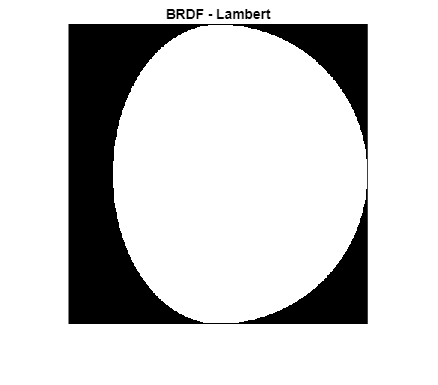

figure()
imshow(brdfLam, [0, max(brdfLam, [], 'all')]) 
title("BRDF - Lambert")

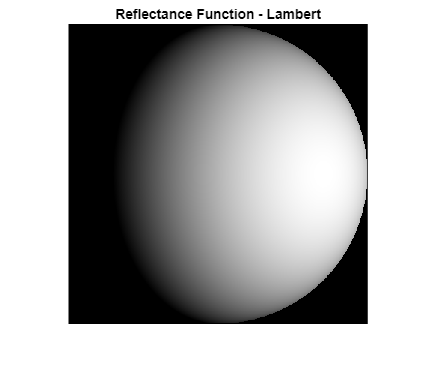


rLam = getReflVals(brdfLam, sphereObj, sphereMask);

figure()
imshow(rLam, [0, max(rLam, [], 'all')])
title("Reflectance Function - Lambert")

## Reflectance Model Comparison

To compare the Lambert and lunar-Lambert reflectance models, we will generate two `OrthoSphere` objects with a 0 and 45 degree phase angles, respectively.

R = 200;
g = [0 pi/4];

SO1 = sonic.OrthoSphere(R, g(1));
SO2 = sonic.OrthoSphere(R, g(2));

As we did previously, we will use a scalar albedo for all the reflectance models.

AL = 0.25/4; 
AL_ss = 0.25;
sigma = 0.5;

lam = sonic.Lambert(AL);
LL_McEwen = sonic.LunarLambert(AL_ss/8, 'McEwenCubic');
LS = sonic.LommelSeeliger(AL_ss);
ON = sonic.OrenNayar(AL, sigma);

Use these reflectance models on the OrthoSphere objects and display your results with

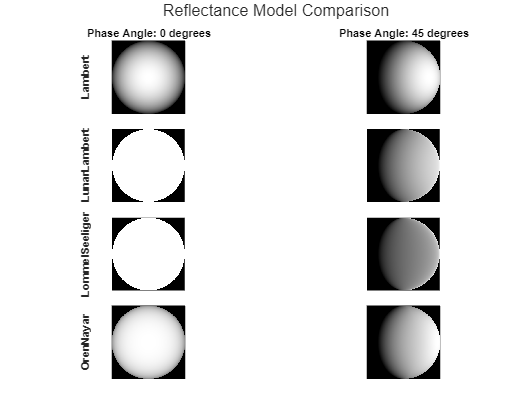

% Calculate BRDFs
[brdfLam_SO1, lam_SM1] = SO1.calcRefl(lam);
[brdfLam_SO2, lam_SM2] = SO2.calcRefl(lam);

[brdfLL_SO1, LL_SM1] = SO1.calcRefl(LL_McEwen);
[brdfLL_SO2, LL_SM2] = SO2.calcRefl(LL_McEwen);

[brdfLS_SO1, LS_SM1] = SO1.calcRefl(LS);
[brdfLS_SO2, LS_SM2] = SO2.calcRefl(LS);

[brdfON_SO1, ON_SM1] = SO1.calcRefl(ON);
[brdfON_SO2, ON_SM2] = SO2.calcRefl(ON);

% Calcuate reflectance function values
rLam_SO1_RF = getReflVals(brdfLam_SO1, SO1, lam_SM1);
rLam_SO2_RF = getReflVals(brdfLam_SO2, SO2, lam_SM2);

rLL_SO1_RF = getReflVals(brdfLL_SO1, SO1, LL_SM1);
rLL_SO2_RF = getReflVals(brdfLL_SO2, SO2, LL_SM2);

rLS_SO1_RF = getReflVals(brdfLS_SO1, SO1, LS_SM1);
rLS_SO2_RF = getReflVals(brdfLS_SO2, SO2, LS_SM2);

rON_SO1_RF = getReflVals(brdfON_SO1, SO1, ON_SM1);
rON_SO2_RF = getReflVals(brdfON_SO2, SO2, ON_SM2);

% Display reflectance values
figure()
t = tiledlayout(4, 2, "TileSpacing", 'tight', 'Padding', 'tight');

nexttile()
imshow(rLam_SO1_RF, [0 max(rLam_SO1_RF, [], 'all')])
ylabel("Lambert", 'FontWeight','bold')
title("Phase Angle: 0 degrees")

nexttile()
imshow(rLam_SO2_RF, [0 max(rLam_SO2_RF, [], 'all')])
title("Phase Angle: 45 degrees")

nexttile()
imshow(rLL_SO1_RF, [0 max(rLL_SO1_RF, [], 'all')])
ylabel("LunarLambert", 'FontWeight','bold')

nexttile()
imshow(rLL_SO2_RF, [0 max(rLL_SO2_RF, [], 'all')])

nexttile()
imshow(rLS_SO1_RF, [0 max(rLS_SO1_RF, [], 'all')])
ylabel("LommelSeeliger", 'FontWeight','bold')

nexttile()
imshow(rLS_SO2_RF, [0 max(rLS_SO2_RF, [], 'all')])

nexttile()
imshow(rON_SO1_RF, [0 max(rON_SO1_RF, [], 'all')])
ylabel("OrenNayar", 'FontWeight','bold')

nexttile()
imshow(rON_SO2_RF, [0 max(rON_SO2_RF, [], 'all')])

title(t, "Reflectance Model Comparison")

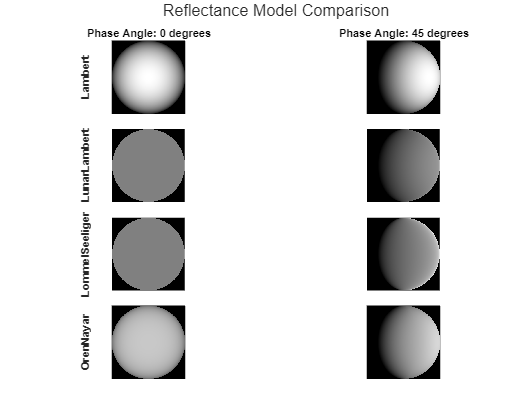

% Determine maximum reflectance value across all models for normalization
maxRefl = max([rLam_SO1_RF rLam_SO2_RF rLL_SO1_RF rLL_SO2_RF rLS_SO1_RF rLS_SO2_RF rON_SO1_RF rON_SO2_RF], [], 'all');

% Display reflectance values
figure()
t = tiledlayout(4, 2, "TileSpacing", 'tight', 'Padding', 'tight');

nexttile()
imshow(rLam_SO1_RF, [0 maxRefl])
ylabel("Lambert", 'FontWeight','bold')
title("Phase Angle: 0 degrees")

nexttile()
imshow(rLam_SO2_RF, [0 maxRefl])
title("Phase Angle: 45 degrees")

nexttile()
imshow(rLL_SO1_RF, [0 maxRefl])
ylabel("LunarLambert", 'FontWeight','bold')

nexttile()
imshow(rLL_SO2_RF, [0 maxRefl])

nexttile()
imshow(rLS_SO1_RF, [0 maxRefl])
ylabel("LommelSeeliger", 'FontWeight','bold')

nexttile()
imshow(rLS_SO2_RF, [0 maxRefl])

nexttile()
imshow(rON_SO1_RF, [0 maxRefl])
ylabel("OrenNayar", 'FontWeight','bold')

nexttile()
imshow(rON_SO2_RF, [0 maxRefl])

title(t, "Normalized Reflectance Model Comparison")

## Summary

Rendering an orthographic projection of a sphere using a sonic.Reflectance boils down to three lines of code:

R = 200;    
g = 0;     
AL = 1;     

sphereObj = sonic.OrthoSphere(R, g);
reflObj = sonic.Lambert(AL);
BRDF = sphereObj.calcRefl(reflObj);

## Supporting Functions

The following function can be used to obtain reflectance function values from the BRDFs for a given sphere.

function reflVals = getReflVals(brdf, sphereObj, sphereMask)
    %% reflVals = getReflVals(r, txt, sphereObj, sphereMask)
    %   Calculates reflectance function values for OrthoSphere
    %   given BRDFs
    %
    %   Inputs:
    %       - r: BRDF values 
    %       - sphereObj: sonic.OrthoSphere object
    %       - sphereMask: logical mask for points on sphere
    %   Outputs:
    %       - reflVals: reflectance values
    % 

    
    % Obtain incidence angles from sphereObj
    i = sphereObj.i;

    % Reshape i to match BRDF matrix using the imgSize property of
    % sphereObj
    i = reshape(i, sphereObj.imgSize, sphereObj.imgSize);
    
    % Calculate cos(i) - needed to calculate reflectance function values
    % given BRDF
    cosi = cos(i);
    
    % Calculate reflectance function values
    reflVals = -1*ones(sphereObj.imgSize);
    reflVals(sphereMask) = brdf(sphereMask).*cosi(sphereMask);
end